% This is a gaussian process because I'm representing lines y=wt for which
% w is a normally-distributed variable. If w is normally distributed, also
% wt is normally distributed (for any value of t). Moreover, any
% n-dimensional vector (for arbitrary n) (w*t1, ..., w*tn) is a
% multivariate gaussian distribution. This satisfies the definition of a
% gaussian process

w = randn(1000,1);

t = [-10 10];

figure; hold on
for i = 1 : numel(w)
    plot(t, w(i)*t)
end


## Stupid proof

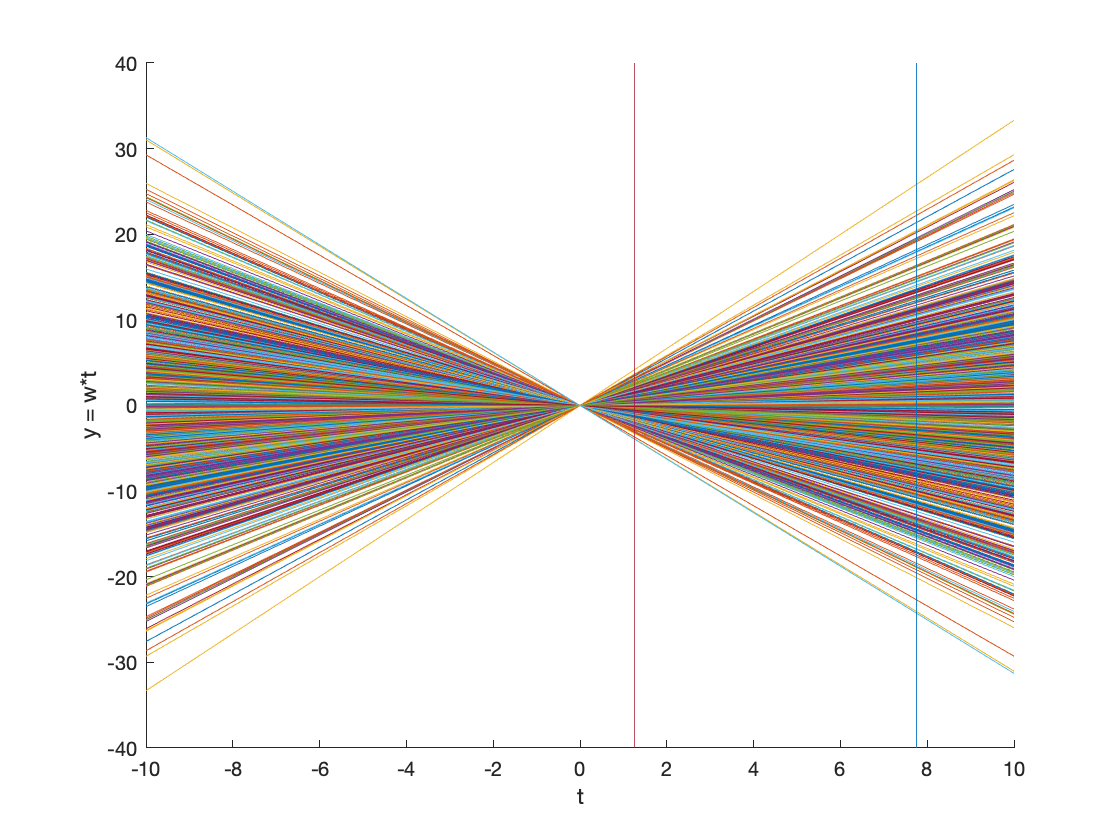


% I select two values of t randomly (to demonstrate that this works for every value of t)
t1 = 10*rand(1); t2 = 10*rand(1);

plot([t1 t1], [-40 40])
plot([t2 t2], [-40 40])
xlabel('t'); ylabel('y = w*t')

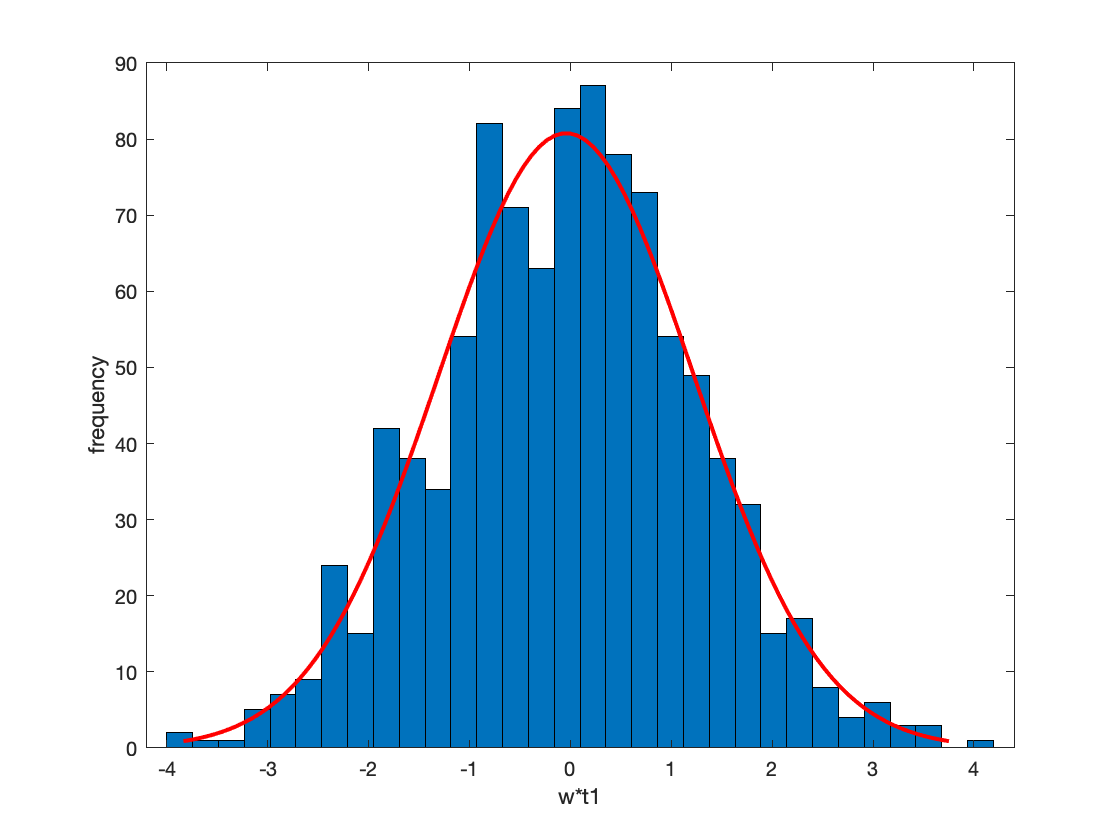


figure
histfit(w*t1)
xlabel('w*t1'); ylabel('frequency')

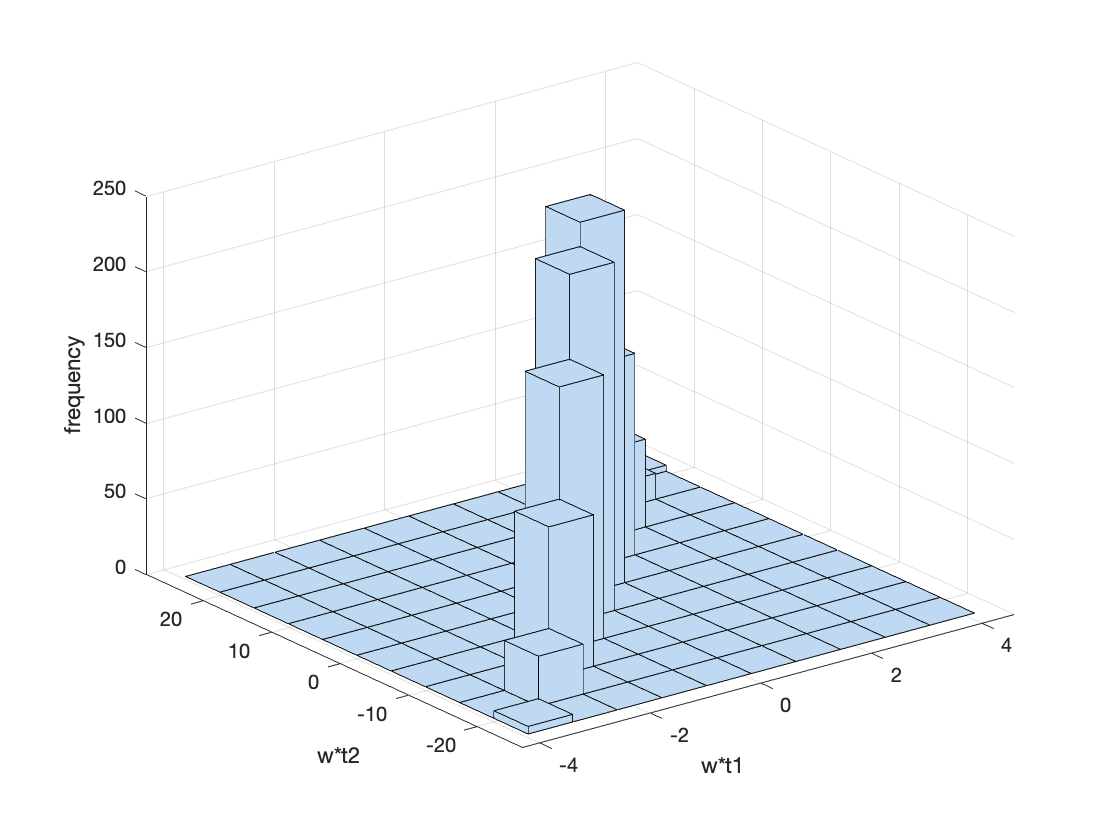


figure
hist3([w*t1 w*t2])
xlabel('w*t1'); ylabel('w*t2'); zlabel('frequency')